clear all
syms x(t) y(t) T(t)

m=1; r=2; g=1;

eqn1 = m*diff(x(t), 2) == T(t)/r*x(t);
eqn2 = m*diff(y(t), 2) == T(t)/r*y(t) - m*g;
eqn3 = x(t)^2 + y(t)^2 == r^2;
DEs=[eqn1;eqn2]; posnConstraints=eqn3;
vars = [y; x; T];

Found multiple suitable values for Dyt:
 	-1.732051
	1.732051
Arbitrarily selecting the first one.
Found multiple suitable values for y:
 	1.732051
	-1.732051
Arbitrarily selecting the first one.
Initial Conditions:
Y0/YP0:
y: 1.732051 yt:-1.732051
x: 1.000000 xt:3.000000
T: -5.133975 Tt:0.000000
Dyt: -1.732051 Dytt:-5.446152
Dxt: 3.000000 Dxtt:-2.566987


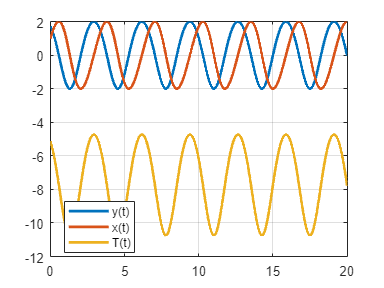

soln=mechanicsAsDAE(DEs,posnConstraints,[],vars,0,20,{"x==1","Dxt==3"});

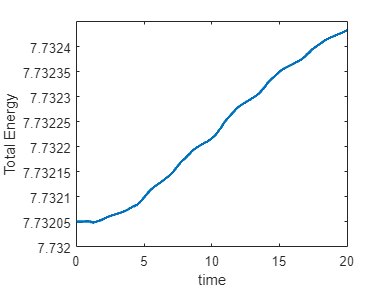


KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Here is a more symbolic approach. 
[DEs,PP]=analyzeSystem([eqn1,eqn2],eqn3,[],[x,y,T],[y,diff(y)])

There are 5 equations, and 3 unknown time-varying functions.
The algebraic (force) functions are:
T(t)

Adding in all constraints, and counting pure symbols (so that x, Dxt, Dxtt count as 3 symbols) I get:
equations: 5
symbols:7
free parameters: 2.

Expected number of state variables: 2

Warning! There are multiple branches for diff(y(t), t, t). This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dxt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dxtt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for T. This likely means that this dynamical system is piecewise-defined in terms of the state variabl

$$DEs = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{4\,y\left(t\right)\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+{y\left(t\right)}^{4}-8\,{y\left(t\right)}^{2}+16}{4\,\left({y\left(t\right)}^{2}-4\right)}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=-\frac{y\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)}{\sigma_{2}}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{\sigma_{1}}{4\,\sigma_{2}}\\ T\left(t\right)=\frac{\sigma_{1}}{2\,\left({y\left(t\right)}^{2}-4\right)}\\ x\left(t\right)=\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+{y\left(t\right)}^{3}-4\,y\left(t\right)\\ \sigma_{2}=\sqrt{4-{y\left(t\right)}^{2}} \end{array}$$

soln=timeStepODESystem(DEs,[y],[y==1,diff(y)==0],[0,20],PP)

soln = struct with fields:
       t: [496×1 double]
       y: [496×1 double]
     Dyt: [496×1 double]
     Dxt: [496×1 double]
    Dxtt: [496×1 double]
       T: [496×1 double]
       x: [496×1 double]


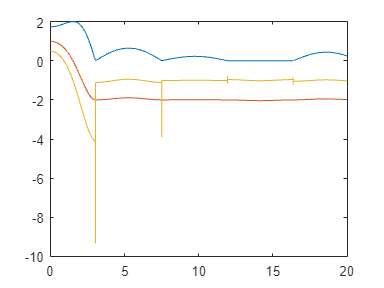

plot(soln.t,real(soln.x),soln.t,real(soln.y),soln.t,real(soln.T))